### c)

clc
close all
clear all

#### convertVariables Class

%classdef convertVariables
%    % Converting from [p,q] to [Q,z] 
%    properties
%        H = 100;
%        Qout
%        k = 0.01;
%        A = 0.1;
%        As = 0.2;
%        z0 = 90;
%        L = 50;
%
%        rho = 1000;
%        g = 9.81;
%
%        I
%        C
%        Rv
%    end
%
%    methods
%        function obj = convertVariables(Qout)
%            obj.Qout = Qout;
%            obj.I = obj.rho * obj.L / (obj.A);
%            obj.C = obj.As / (obj.rho * obj.g);
%            obj.Rv = obj.rho * obj.g * (obj.H - obj.z0 - obj.k * obj.Qout^2) / obj.Qout;
%        end
%    end
%
%    methods(Static)
%        function [Q, z] = state2real(p, q, obj)
%            Q = p / obj.I;
%            z = q / obj.As;
%        end
%
%        function [p, q] = real2state(Q, z, obj)
%            p = Q * obj.I;
%            q = z * obj.As;
%        end
%    end
%end

#### Odefun function

(made this before I made the class. Therefore: constants directly inserted)

%function dydt = odefun_ex6(t, y, Qout)
%    % Extract variables from the y vector
%    p = y(1);
%    q  = y(2);
%
%    %From exercise text
%    H = 100;
%    k = 0.01;
%    A = 0.1;
%    As = 0.2;
%    z0 = 90;
%    L = 50;
%
%    rho = 1000;
%    g = 9.81;
%
%    I = rho*L/A;
%    C = As/(rho*g);
%    Rv = rho*g*(H-z0-k*Qout^2)/Qout;
%
%    % Define the system of ODEs
%    p_dot = rho*g*H - q/C - p/I*(Rv + rho*g*(p/I)*k);
%    q_dot = p/I - Qout;
%
%    % Pack the derivatives into a column vector
%    dydt = [p_dot; q_dot];
%end

Setting the initial condition

Q_start = 1;
z_start = 100;

Qout = 1;
converter = convertVariables(Qout);

[p_start, q_start] = convertVariables.real2state(Q_start, z_start, converter);  % Call the method with the instance

Simulate to *tmax*

tmax = 70;
[t, Y] = ode45(@(t, y) odefun_ex6(t, y, Qout),[0 tmax], [p_start q_start]);
p = Y(:,1);
q = Y(:,2);

[Q, z] = convertVariables.state2real(p, q, converter);  % Call the method with the instance

Plots

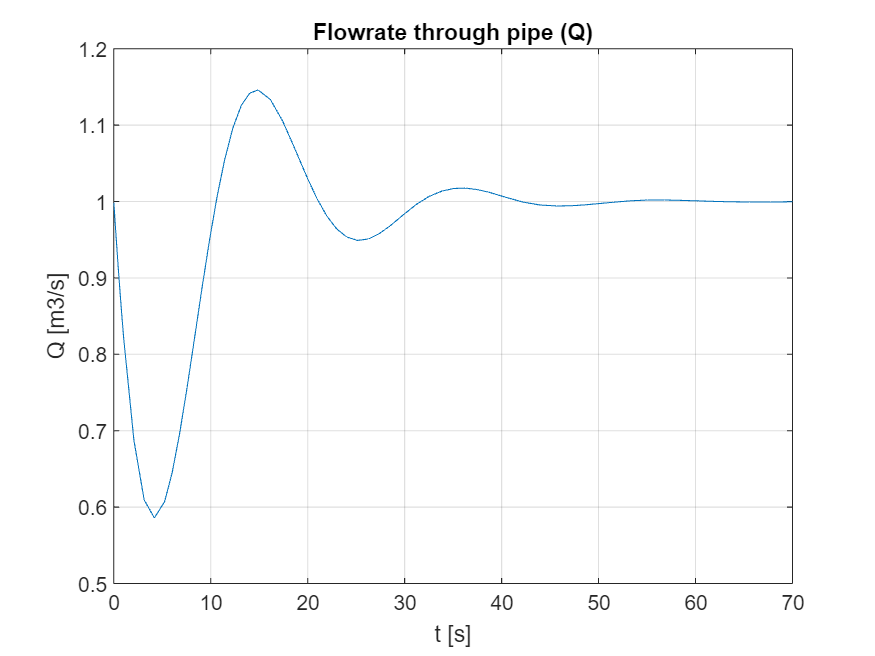

plot(t,Q)
title("Flowrate through pipe (Q)")
xlabel("t [s]")
ylabel("Q [m3/s]")
grid on

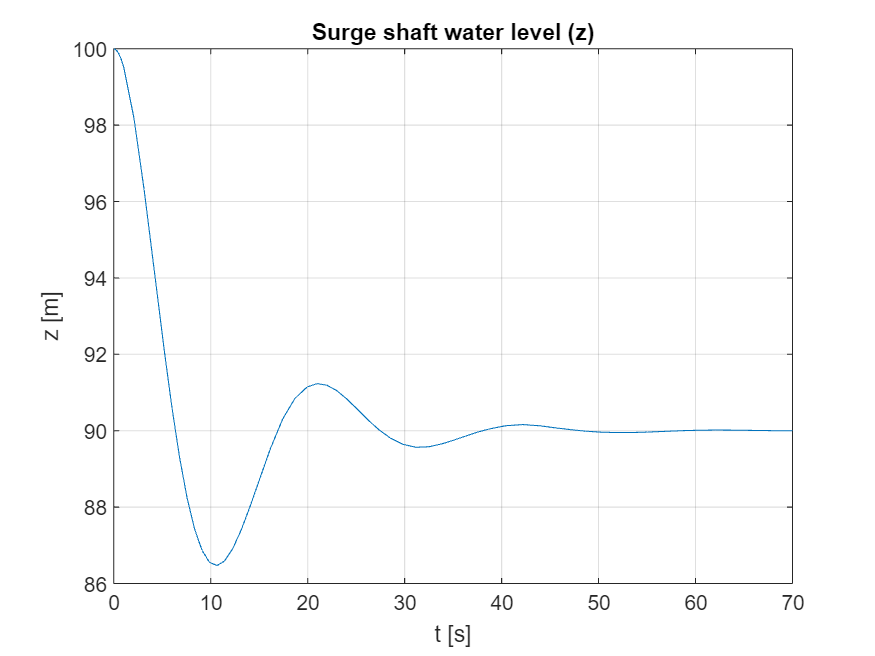

plot(t,z)
title("Surge shaft water level (z)")
xlabel("t [s]")
ylabel("z [m]")
grid on

### d)

The initial conditions now reads the steady state values from c)

Q_start = 1; 
z_start = 90;

Change the Qout value in the *converter* instance (from *convertVariables* class) to 90% of it original value  $\left(0\ldotp 9\;\frac{m^3 }{s}\right)$. Does not make a new instance of the class, because we assume that Rv resistance is the same as before, i.e designed for z0 = 90m.

Qout = 0.9;
converter.Qout = Qout;

[p_start, q_start] = convertVariables.real2state(Q_start, z_start, converter);  

Simulate to *tmax*

tmax = 70;
[t, Y] = ode45(@(t, y) odefun_ex6(t, y, Qout),[0 tmax], [p_start q_start]);
p = Y(:,1);
q = Y(:,2);

[Q, z] = convertVariables.state2real(p, q, converter); 

Plots

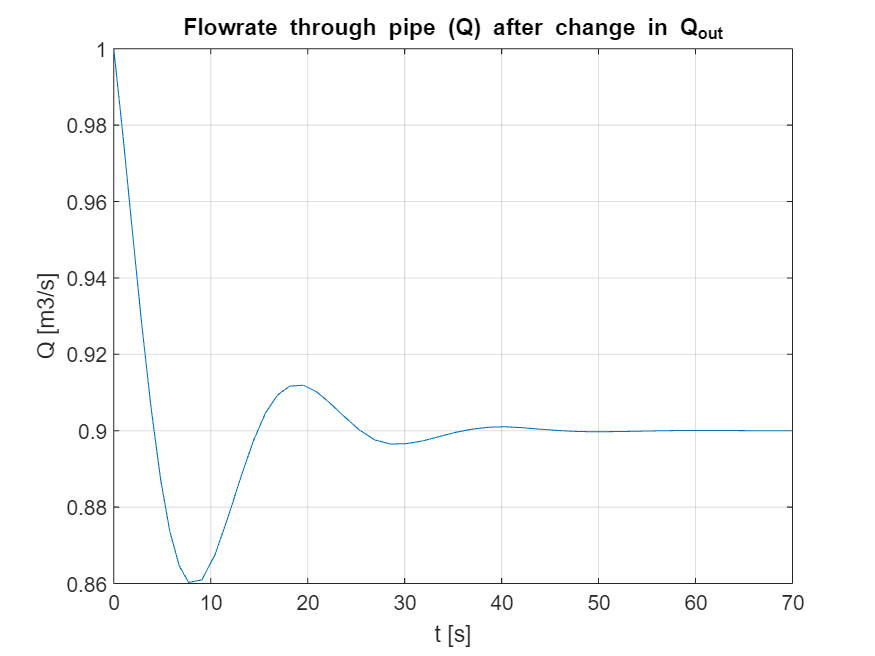

plot(t,Q)
title("Flowrate through pipe (Q) after change in Q_{out}")
xlabel("t [s]")
ylabel("Q [m3/s]")
grid on

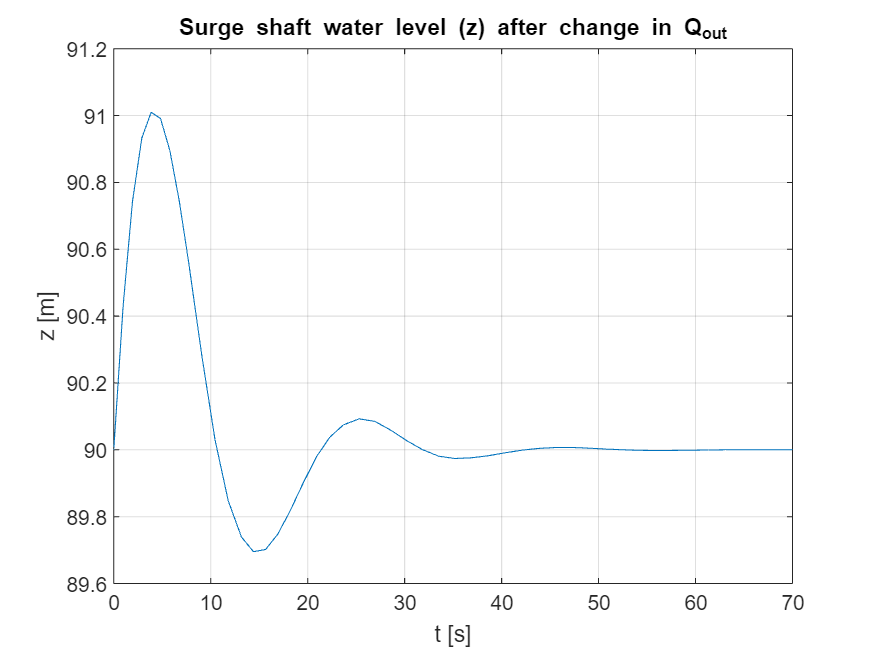

plot(t,z)
title("Surge shaft water level (z) after change in Q_{out}")
xlabel("t [s]")
ylabel("z [m]")
grid on

The results make sense because when the Qout suddenly drops, then Q>Qout will fill the surge shaft, and after a while, the Q value will drop low enough to Q = Qout to obtain mass balance. Then water level will drop to the level the resistance Rv was initially designed for.

### e)

:)